# FFT Examples - Gibbs phenomenon

Plot the frequency representation of the sinc signal by using the FFT function.

The sinc signal must be designed considering several lengths.

Don't use the *sinc* matlab function. Compute the sinc manually and pay attention to the ratio 0/0.

**Parameters**

- 
$$x\left(t\right)=\frac{\sin \left(2\pi {\;F}_c \;t\right)}{2\pi \;F_c \;t}$$


- Length of *n *= [17, 65, 257]

- 
$$T_s =1\;\left\lbrack \textrm{ms}\right\rbrack$$


- 
$$F_c =250\;\left\lbrack \textrm{Hz}\right\rbrack$$


## **Discretization of the sinc function**

Let's consider the continuous sinc function:


$$x\left(t\right)=\frac{\sin \left(2\pi {\;F}_c \;t\right)}{2\pi \;F_c \;t}$$


The discretizazion can be obtained with $t={\textrm{nT}}_s$


$$x\left\lbrack n\right\rbrack =\frac{\sin \left(2\pi \;F_N \;n\right)}{2\pi \;F_N \;n}$$


where $F_N =F_c /F_s$ is the normalized frequency.

When you compute the sinc output, you must compensate the NaN value introduced by the ratio 0/0.

## Clear

clc;        % 'clc' cleras all the text from the Command Window
clear;      % 'clear' removes all variables from the current workspace
close all;  % 'close all' deletes all figures whose handles are not hidden.

## Parameters

len = [17, 65, 257];
Ts = 1e-3;
Fs = 1/Ts;
Fc = 250;
F_N = Fc/Fs;


## Exercise

n_lim = (len(1)-1)/2;
n  = -n_lim:+n_lim;
x0 = sin(2*pi*F_N*n) ./ (2*pi*F_N*n);

n_lim = (len(2)-1)/2;
n  = -n_lim:1:+n_lim;
x1 = sin(2*pi*F_N*n) ./ (2*pi*F_N*n);

n_lim = (len(3)-1)/2;
n  = -n_lim:1:+n_lim;
x2 = sin(2*pi*F_N*n) ./ (2*pi*F_N*n);

% NaN Check
x0(isnan(x0)) = 1;
x1(isnan(x1)) = 1;
x2(isnan(x2)) = 1;


## Plot

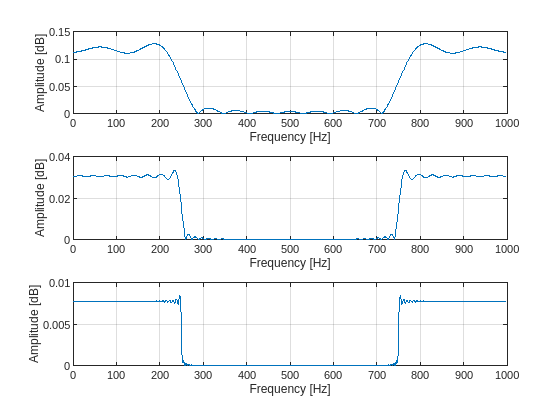

nFFT = 2^10;
Xf_0 = fft(x0,nFFT);
Xf_1 = fft(x1,nFFT);
Xf_2 = fft(x2,nFFT);

Xf_0 = abs(Xf_0);
Xf_1 = abs(Xf_1);
Xf_2 = abs(Xf_2);

f_ax_0 = (0:length(Xf_0)-1)/length(Xf_0) * Fs;
f_ax_1 = (0:length(Xf_1)-1)/length(Xf_1) * Fs;
f_ax_2 = (0:length(Xf_2)-1)/length(Xf_2) * Fs;

figure
subplot(3,1,1)
  plot(f_ax_0,Xf_0)
  grid on
  xlabel('Frequency [Hz]')
  ylabel('Amplitude [dB]')
subplot(3,1,2)
  plot(f_ax_1,Xf_1)
  grid on
  xlabel('Frequency [Hz]')
  ylabel('Amplitude [dB]')
subplot(3,1,3)
  plot(f_ax_2,Xf_2)
  grid on
  xlabel('Frequency [Hz]')
  ylabel('Amplitude [dB]')